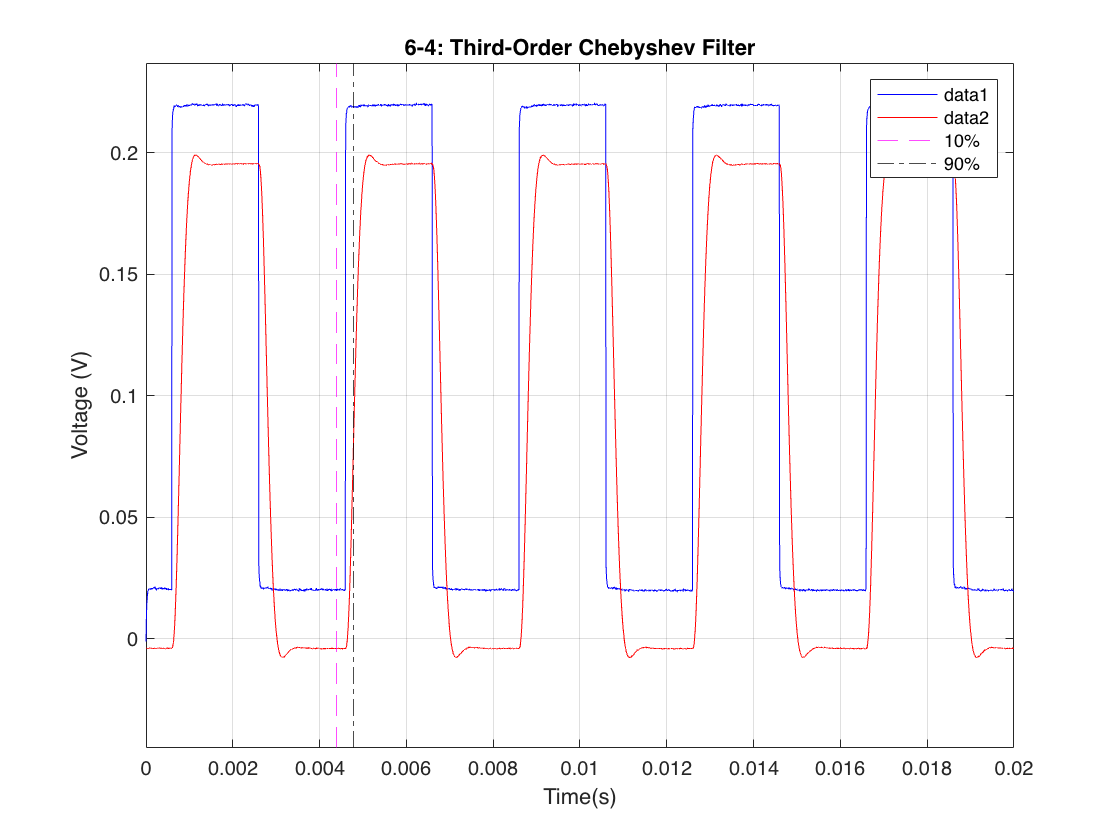

file='/Users/madi/Documents/GitHub/MATLAB/Lab6/Osc/Lab 6-3 Osc.txt';
fileID=fopen(file);
data=textscan(fileID, '%s %s %s %s','Delimiter','\t');
fclose(fileID);

w=0:0.000008:0.02;

data1=data{1,2};
data1=str2double(data1);
data1=data1(5:2505);
data2=data{1,4};
data2=str2double(data2);
data2=data2(5:2505);

plot(w,data1,'b')
hold on 
grid on 
plot(w,data2,'r')
ylim([-.02 .22])

title('6-4: Third-Order Chebyshev Filter');
hold on;
xlabel('Time(s)');
hold on;
ylabel('Voltage (V)');
hold on;
xline(0.0044,'--','color','m','DisplayName','10%');
hold on
xline(0.00478,'-.','color','black','DisplayName','90%');
hold on
legend
hold off

xlim([-0.0000 0.0200])
ylim([-0.010 0.230])

xlim([0.0000 0.0200])
ylim([-0.045 0.237])

maxOvershoot61=max(data2)

maxOvershoot61 = 0.1993